Previously, in 2024-11-18_simulated_small_signal_response, a current controller was wrapped around the  reduced order transfer function from $\phi \;\left(s\right)$ to $i_{\textrm{out}} \left(s\right)$:


$$\frac{i_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{2\textrm{LsNf}}$$


This was obtained from Basso:   

    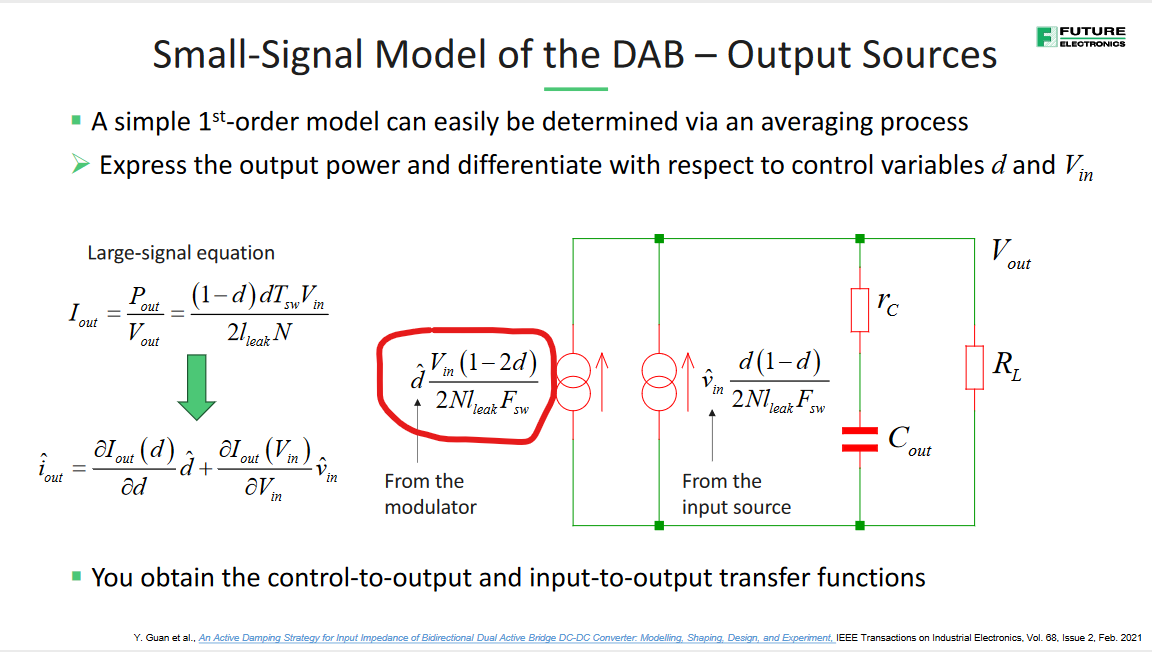

[1]

C. Basso, “An Introduction to the Dual Active Bridge Converter or DAB”.  

I want a transfer function from $\phi \;$ to $v_{\textrm{out}}$.

starting from the large signal equation: $P_{out} = I_{out}V_{out} = \frac{(1-\phi)\phi T_{sw}V_{out}V_{in}}{2LN}$

Assuming 100% efficiency, 


$$P_{in} = I_{in}V_{in} = \frac{(1-\phi)\phi T_{sw}V_{out}V_{in}}{2LN}$$



$$ I_{in} = \frac{(1-\phi)\phi T_{sw}V_{out}}{2LN}$$



$$V_{out} = \frac{ 2LN I_{out} }{ (1-\phi)\phi T_{sw} }$$



$$\hat{v}_{out} = \frac{\partial{V_{out}(\phi)}}{\partial{\phi}} \hat{\phi} +  \frac{\partial{V_{out}(I_{out})}}{\partial{I_{out}}} \hat{i}_{out}$$


Ignoring the second partial, and evaluating only the first:

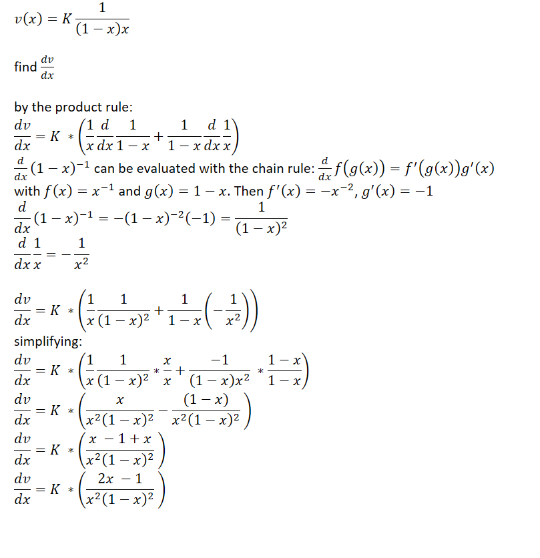


$$ \frac{\partial{V_{out}(\phi)}}{\partial{\phi}} = \frac{\hat{v}_{out}}{\hat{\phi}}= \frac{2LNI_{out} } { T_{sw} } \frac{2\phi - 1} {\phi^2 (1-\phi)^2}$$


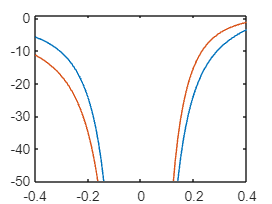

figure;
phi = -0.4:0.01:0.4;
plot(phi, (2.*phi - 1)./(phi.^2 .* (1 - phi).^2));
hold on;
plot(phi, (2.*phi - 1)./(phi.^2));
ylim([-50,1])
xlim([-0.4, 0.4])

This seems cursed. It blows up around $\phi =0$.

Examining the transfer function:


$$ \frac{\hat{v}_{out}(s)}{\hat{\phi}(s)}= \frac{2LsNI_{out} } { T_{sw} } \frac{2\phi - 1} {\phi^2 (1-\phi)^2}$$


- there's a zero at the origin

- the sign of the gain varies with the sign of $I_{\textrm{out}}$

My feeling is that output voltage depends more on the load than the DAB itself, and that the DAB is primarily a current-mode converter.

Perhaps it's better to stick with the $\frac {\hat{i}_{out} (s)} { \hat{\phi}(s)}$ transfer function.


$$\frac{i_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{2\textrm{LsNf}}$$


To linearize it we can use a feedforward term that takes $\phi \;$ and $V_{\textrm{in}}$. But does that equation hold for negative $\phi \;$also? This equation gets the sign correct:

pout = Va*Vb*phi*(1 - abs(phi)) / (2 * f * L * N);


$$P_{out} = \frac{ V_{in}V_{out} \phi (1- |\phi|) } { 2 f LN}$$


The derivative of the absolute value has a discontinuity at the origin. Ignoring that for now...

Separating this into dynamic, feedforward, and constant terms:


$$\frac{i_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{2\textrm{LsNf}}=\frac{1}{s}*\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{1}*\frac{1}{2\textrm{LNf}}$$


The plant essentially turns into an integrator. The feedforward gain of $\left(1-2\phi \;\right)V_{\textrm{in}}$ can be subtracted? from the output of the compensator

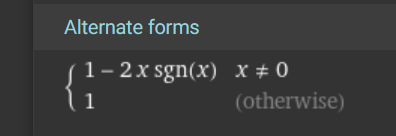

Since I'm planning to feed-forward compensate it, better be correct $\left(1-2\phi \;\textrm{sgn}\left(\phi \right)\;\right)V_{\textrm{in}}$

We want voltage control. The full plant transfer function, including the output capacitor is 


$$\frac{v_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{i_{\textrm{out}} \left(s\right)}{\phi \;\left(s\right)}*Z_{\textrm{cout}}$$



$$\frac{v_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{1}{s}*\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{1}*\frac{1}{2\textrm{LNf}}*\frac{1}{\textrm{sC}}$$


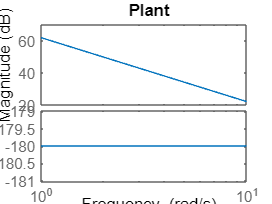

figure;
s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=10e-6;
GpGl = 1/s^2 * 1/(2*L*N*f*C);
bode(GpGl);
title("Plant");

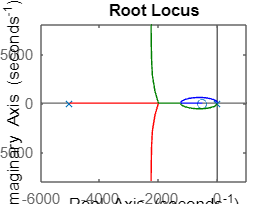

figure;
z = 2 * pi * 80;
p = 2 * pi * 800;
Gc = (s + z)/(s + p);
rlocus(Gc * GpGl);

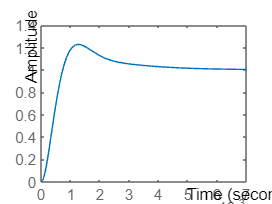


figure;
Gcl = (Gc * GpGl) / (1 + Gc * GpGl);
step(Gcl);

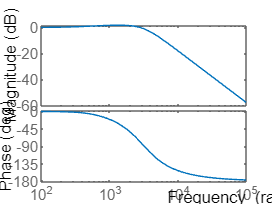


figure;
bode(Gcl);

I tried this in PLECS, but there's steady-state error in the response

`dc_bus_voltage_ctrl.plecs`

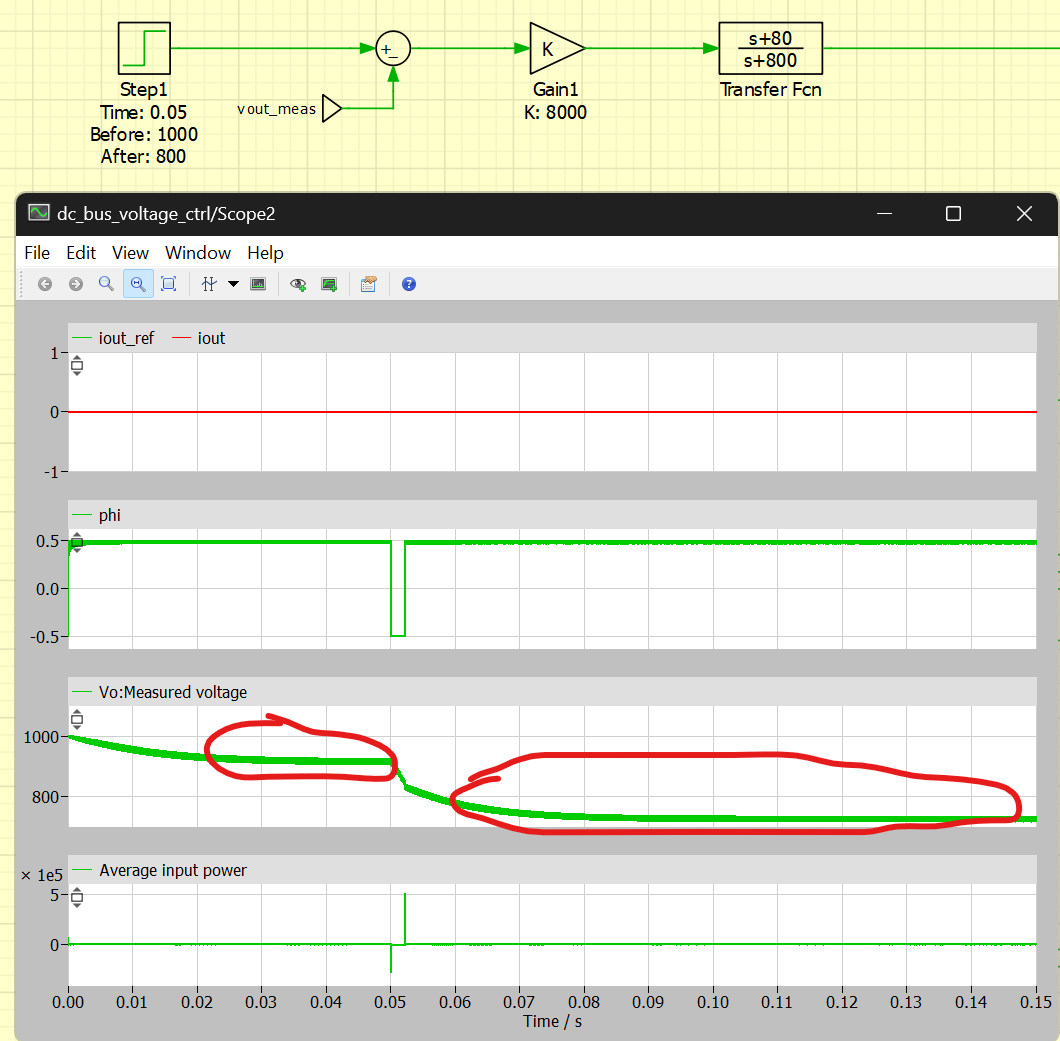

Let's try the good old k-factor method.

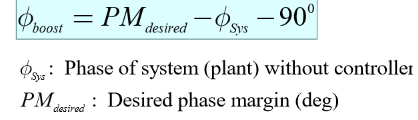

PM_desired = 60;
wc_desired = 2*pi*100;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
phi_boost

phi_boost = 150

Hell yeah, type III or bust

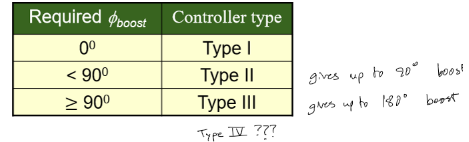

k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z

w_z = 82.7197

w_p

w_p = 4.7726e+03

K_c

K_c = 3.4394e+03

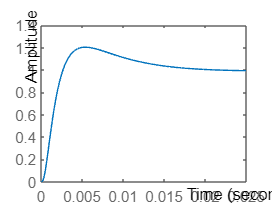


Gc = K_c * Gc_unitygain;
GcGpGl = Gc * GpGl;

figure;
step(GcGpGl / (1 + GcGpGl));

Nice. This is a good place to be. I implemented it in `dc_bus_voltage_ctrl_2.plecs`.

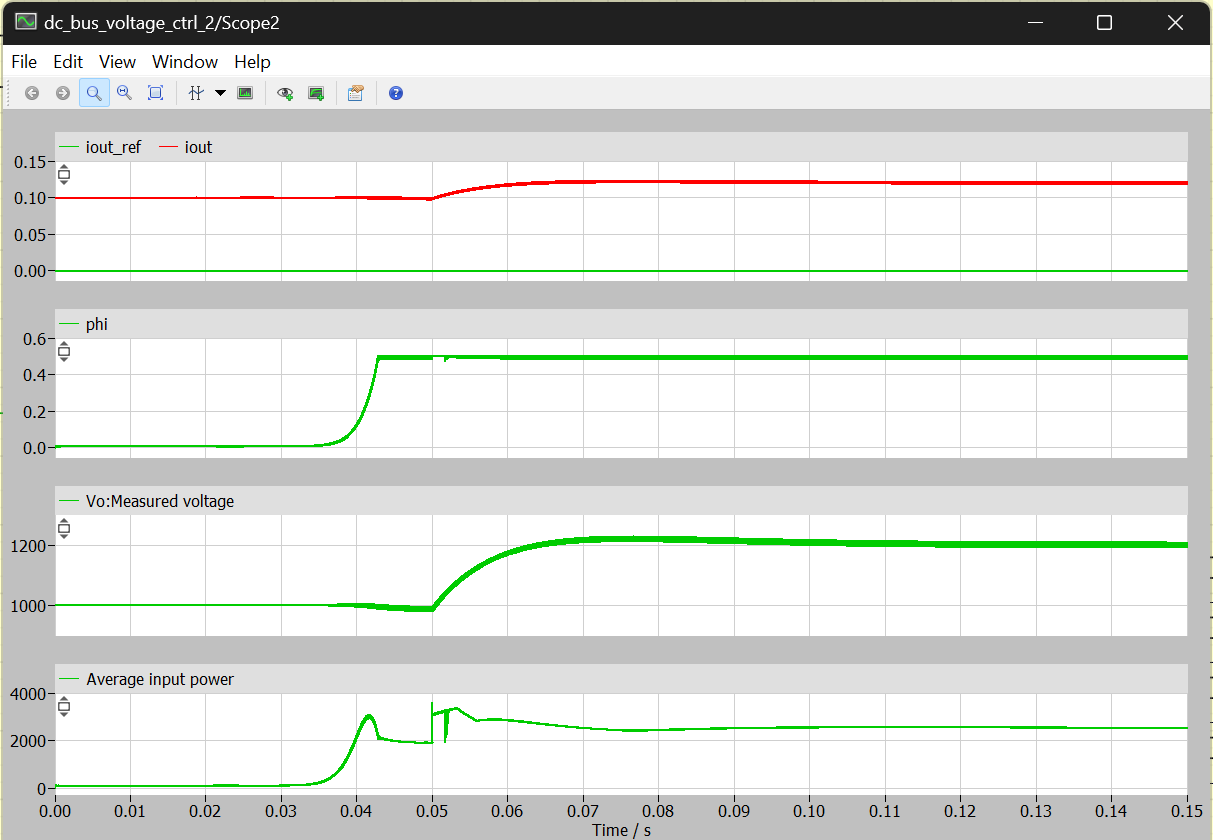

phi is saturating at 0.5

A few potential improvements:

- Further increasing the rated power to improve transient response

- try the feedforward. Observe its effects.

Let's try adding feedforward to compensate for the nonlinearity of the plant: 


$$\frac{i_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{2\textrm{LsNf}}=\frac{1}{s}*\frac{\left(1-2\phi \;\right)V_{\textrm{in}} }{1}*\frac{1}{2\textrm{LNf}}$$


The controller output should be divided by $\left(1-2\phi \;\right)V_{\textrm{in}}$

Unfortunately, this function goes to zero at $\phi =\pm 0\ldotp 5$

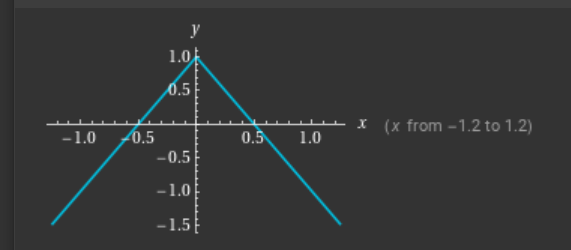,

To avoid the divide-by-zero issue, I can bound the inputs. e.g.: $-0\ldotp 4\le \;\;\phi \le 0\ldotp 4$, $V_{\textrm{in}} \ge 10V$.

Since I'm planning to feed-forward compensate it, better be correct $\left(1-2\phi \;\textrm{sgn}\left(\phi \right)\;\right)V_{\textrm{in}}$

I took a shot at implementing the feed-forward compensator in `dc_bus_voltage_ctrl_3.plecs`, but it's not working as expected.  

I'm not pleased with the response in `dc_bus_voltage_ctrl_2.plecs `for two reasons:

- It's slow

- There's something funny happening where a lot of DC builds up in the primary.

I tried reducing the bandwidth in `dc_bus_voltage_ctrl_4.plecs`. This helped a little, but then I observed that the output capacitance is responsible for the slow transient response.

PM_desired = 60;
wc_desired = 2*pi*20;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);

Unrecognized function or variable 'GpGl'.

phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z
w_p
K_c

k-factor isn't cutting it. I need some damping in the controller to get faster step response.

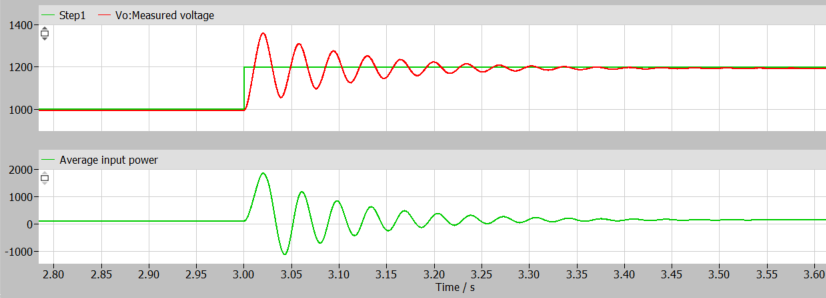

Unless the issue is that capacitance is incorrectly defined in my model?


s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=1e-6;
GpGl = 1/s^2 * 1/(2*L*N*f*C);

PM_desired = 60;
wc_desired = 2*pi*100;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z
w_p
K_c

I updated `dc_bus_voltage_ctrl_4.plecs `to have a 1uF output capacitor (down from 100uF).

That's better, but phi saturates and oscillates. I think the feedforward can help with this. 

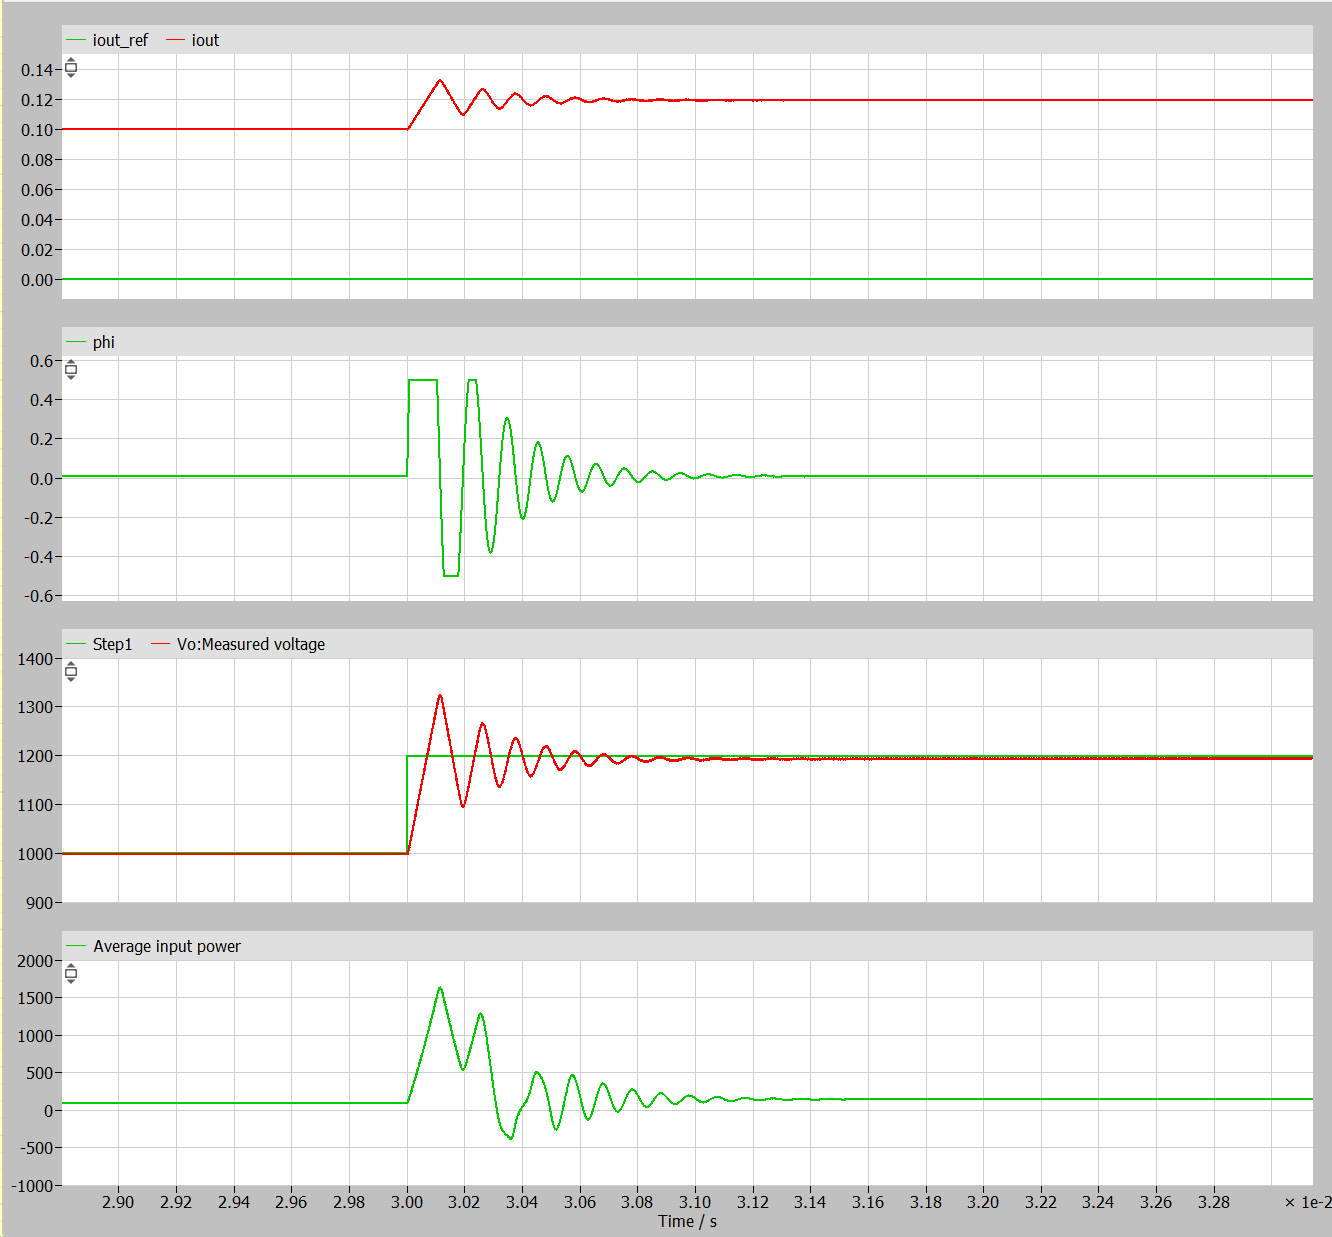

What is the nonlinear term telling us?


$$\frac{v_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{1}{s}*\frac{\left(1-2\phi \;\right){\mathit{\mathbf{V}}}_{\textrm{in}} }{1}*\frac{1}{2\textrm{LNf}}*\frac{1}{\textrm{sC}}$$


It's telling us that the plant gain is nonlinear in $\phi \;$ and in $V_{\textrm{in}\;}$

Here's the $\phi \;$ nonlinearity: 

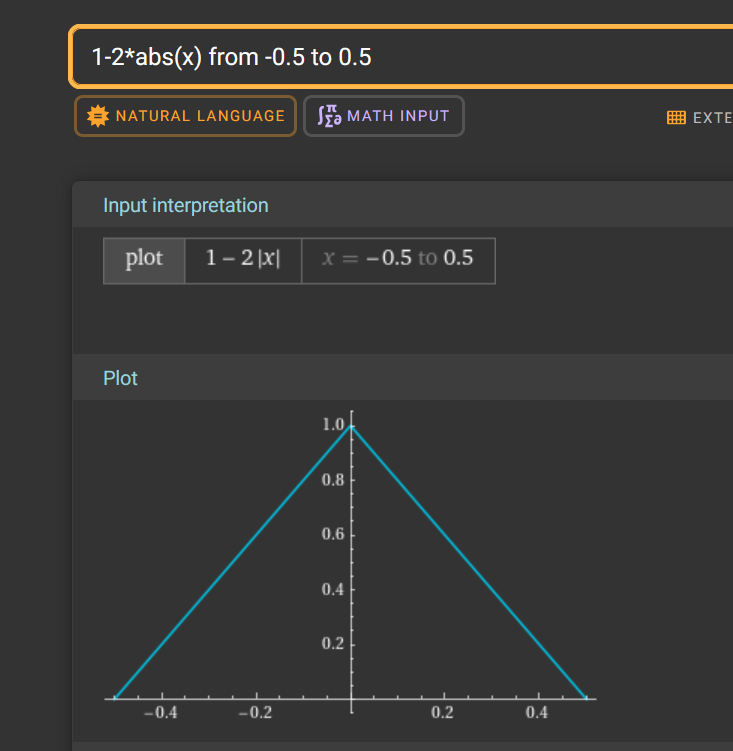

Wait a minute... how about just saturating the integrator?

I tried it in `dc_bus_voltage_ctrl_5.plecs` and it didn't work. I removed the saturation from the integrator and looked at the pre-saturation output value to see what it looks like: 

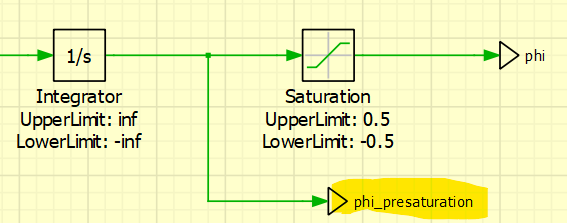

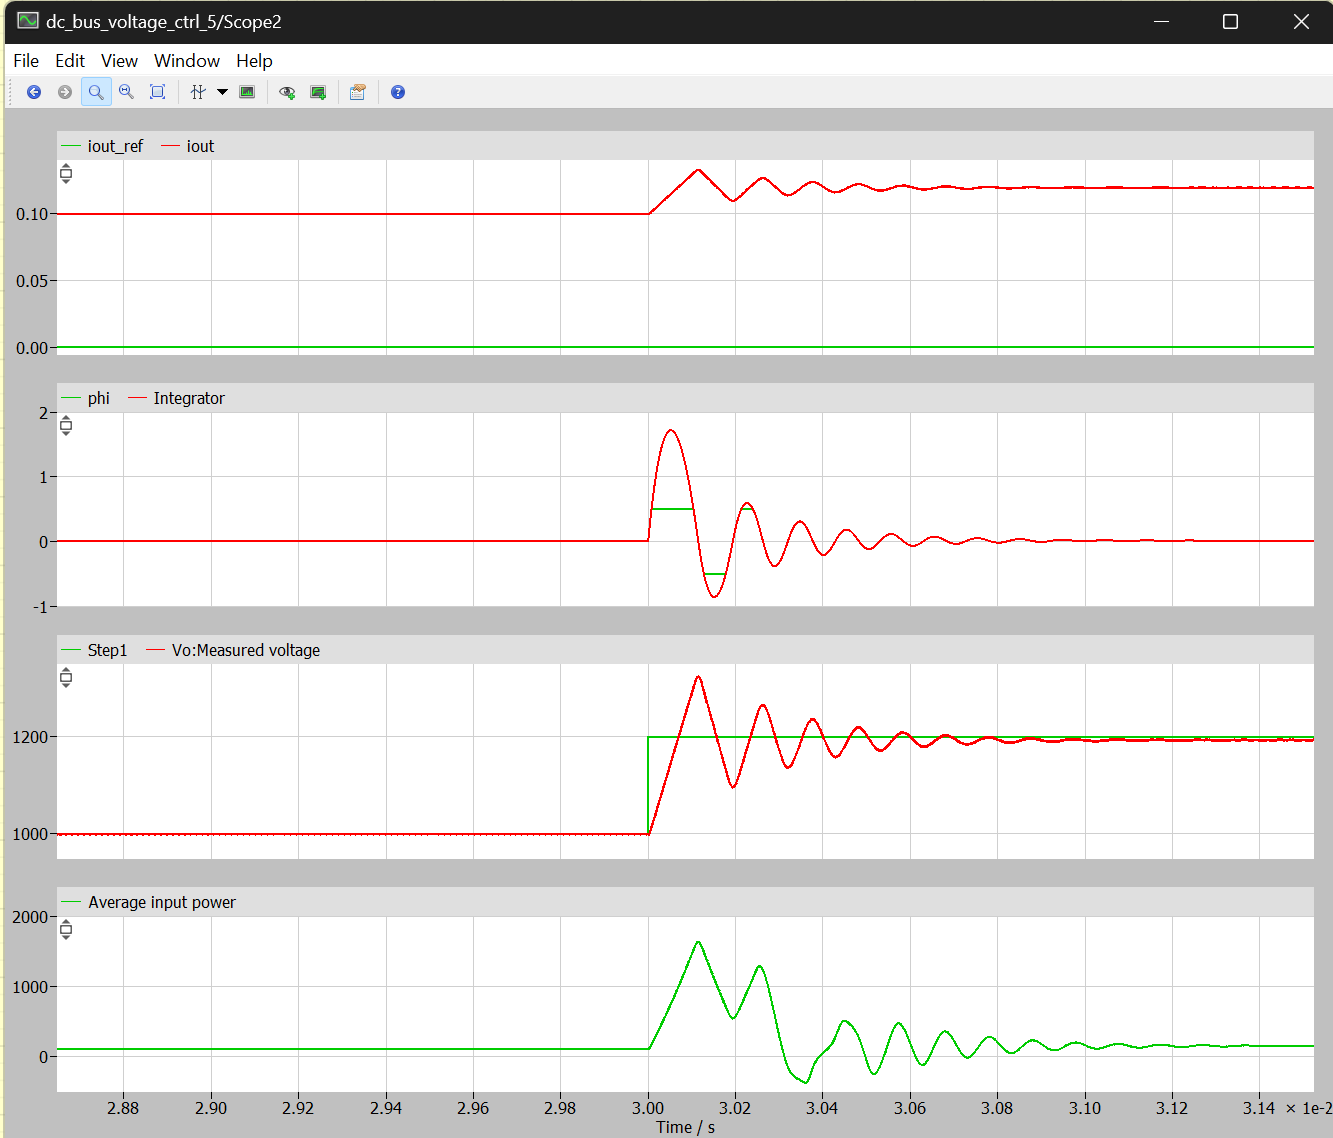

This confirms that the over/undershoot is due to oscillation in the controller.

Does this match the MATLAB system model?

s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=1e-6;
GpGl = 1/s^2 * 1/(2*L*N*f*C);

PM_desired = 60;
wc_desired = 2*pi*100;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z

w_z = 82.7197

w_p

w_p = 4.7726e+03

K_c

K_c = 343.9440

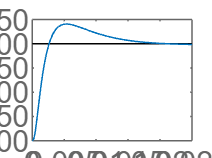


Gc = K_c * Gc_unitygain;
GcGpGl = Gc * GpGl;
figure;
% step the closed loop system from 1000 to 1200
Config = RespConfig('InputOffset', 1000, 'Amplitude', 200);
G_cl = feedback(GcGpGl, 1);
step(G_cl, Config);

Not even close other than the timescale. The MATLAB model is linear and doesn't account for saturation of the control variable.

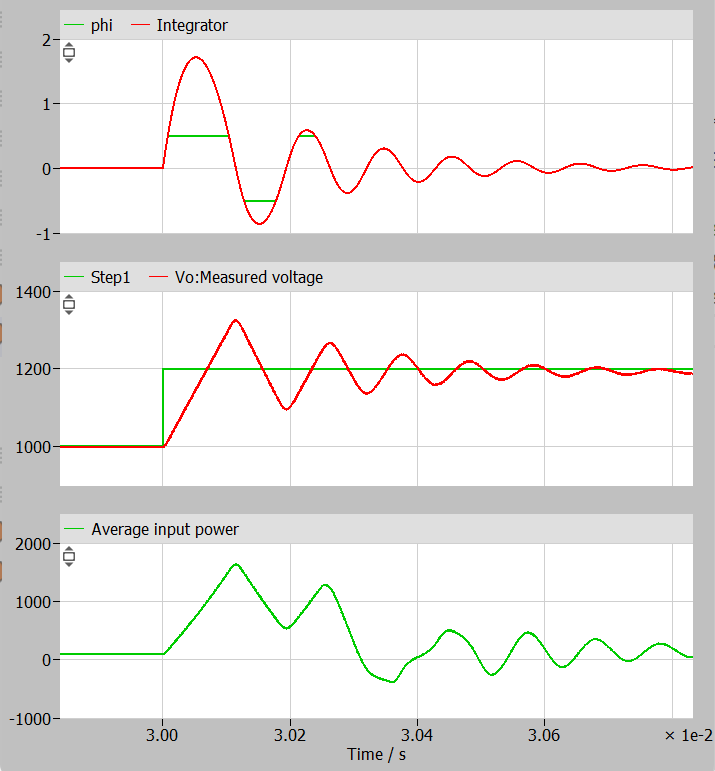

One easy way to fix this problem is to increase the power capability of the stage, but that's a hack.

I just noticed a big error: that the transfer function I've been using up until now `GpGl = 1/s^2 * 1/(2*L*N*f*C) `**is linearized around **$V_{\textrm{in}\;} =1$**.  **It should be linearized around $V_{\textrm{in}} =1000$. Oops. Note the $V_{\textrm{in}} \;$in the plant TF:


$$\frac{v_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{1}{s}*\frac{\left(1-|2\phi |\;\right){\mathit{\mathbf{V}}}_{\textrm{in}} }{1}*\frac{1}{2\textrm{LNf}}*\frac{1}{\textrm{sC}}$$


s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=1e-6;
GpGl = 1/s^2 * 1000/(2*L*N*f*C);

PM_desired = 60;
wc_desired = 2*pi*1000;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z

w_z = 827.1970

w_p

w_p = 4.7726e+04

K_c

K_c = 343.9440

That reduced the gain by a factor of 1000. The output looks, uhh, droopy. I can now turn the bandwidth way up. Rather than making a bunch more copies of the simulation, I'll note the k-factor gains and results here.

`dc_bus_voltage_ctrl_6.plecs`:

wc_desired = 2*pi*100;

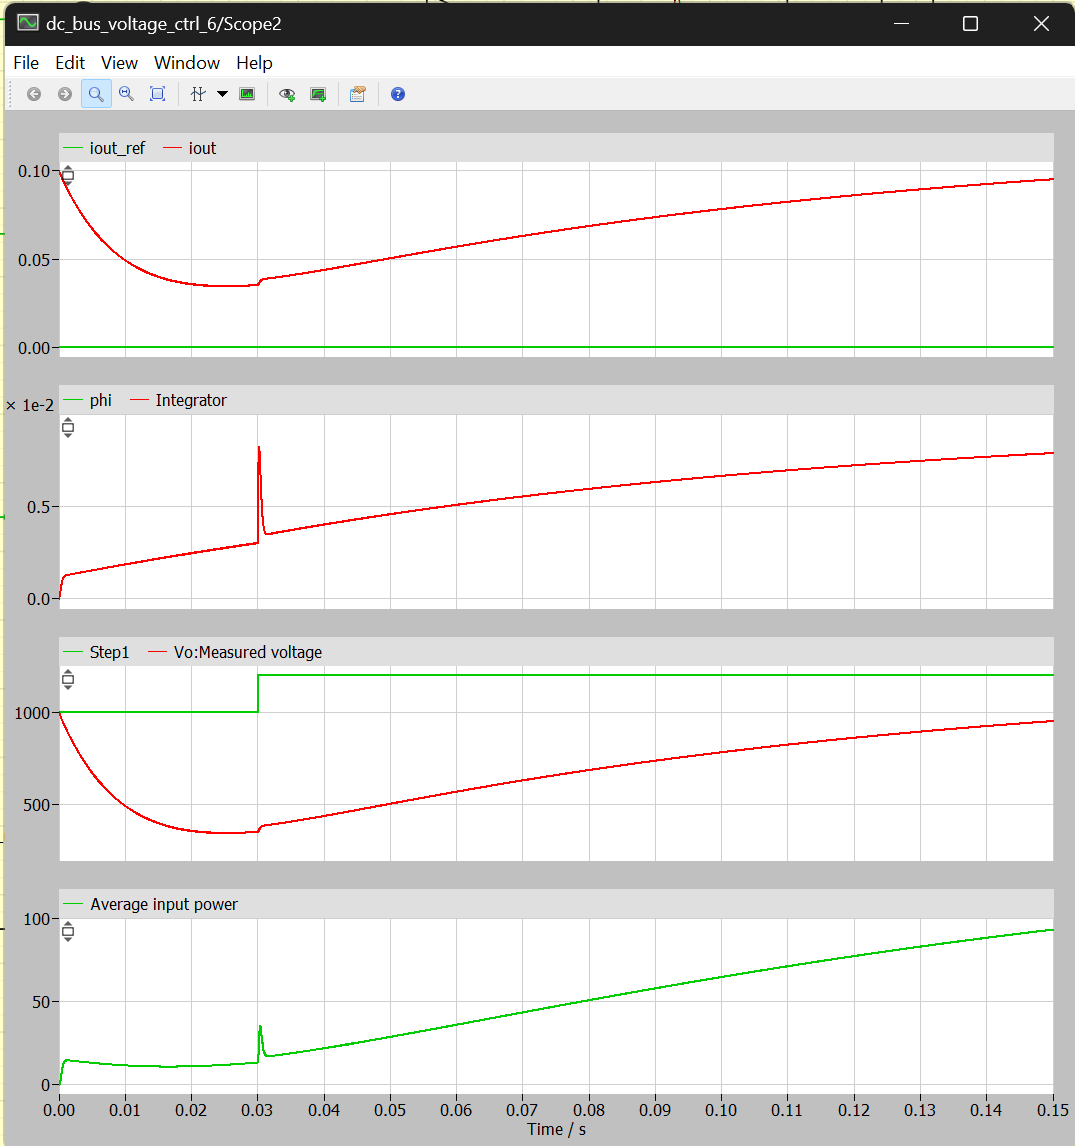

wc_desired = 2*pi*1000;

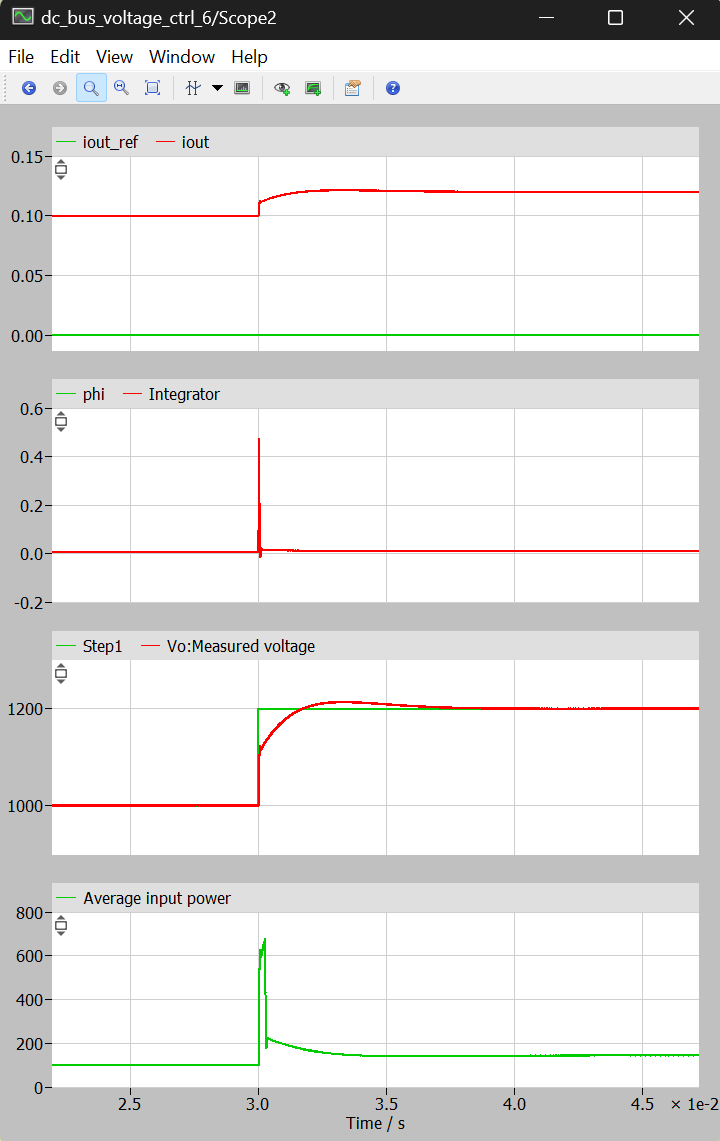

That is a nicer looking step. Zooming in, $\phi \;$just kisses the saturation limit. It's weird that the control variable returns to close to zero well before the system reaches the control setpoint.

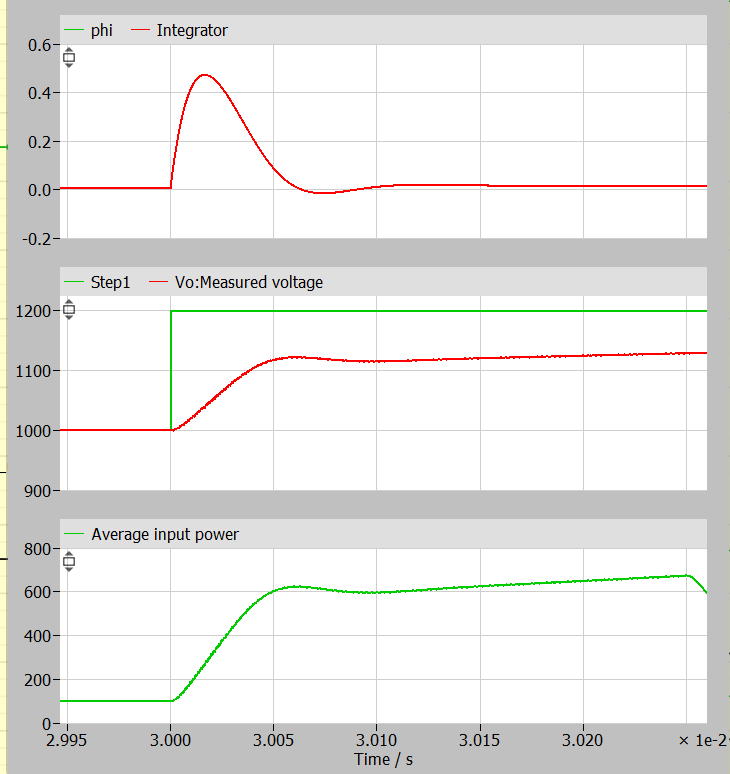

I'm going to take an incremental step towards feedback linearization. I can rewrite the transfer function as


$$\frac{v_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{1}{s}*\frac{\left(1-|2\phi |\;\right)}{1}*\frac{{\;\mathit{\mathbf{V}}}_{\textrm{in}} }{1000}*\frac{1000}{2\textrm{LNf}}*\frac{1}{\textrm{sC}}$$


I've computed a controller for 


$$\frac{v_{\textrm{out}} \left(s\right)}{\phi \left(s\right)}=\frac{1}{s}*\frac{1000}{2\textrm{LNf}}*\frac{1}{\textrm{sC}}$$


that works reasonably well. Now I want to compensate for the remaining coefficients of


$$\frac{\left(1-|2\phi |\;\right)}{1}*\frac{{\;\mathit{\mathbf{V}}}_{\textrm{in}} }{1000}$$


in the plant gain. Quantitatively, if $V_{\textrm{in}}$ increases, the plant gain increases. This should result in decreased compensator gain. I should multiply the error by $\frac{1}{\frac{V_{\textrm{in}} }{1000}}\;$or $\frac{1000}{V_{\textrm{in}} }$. Let's try it.

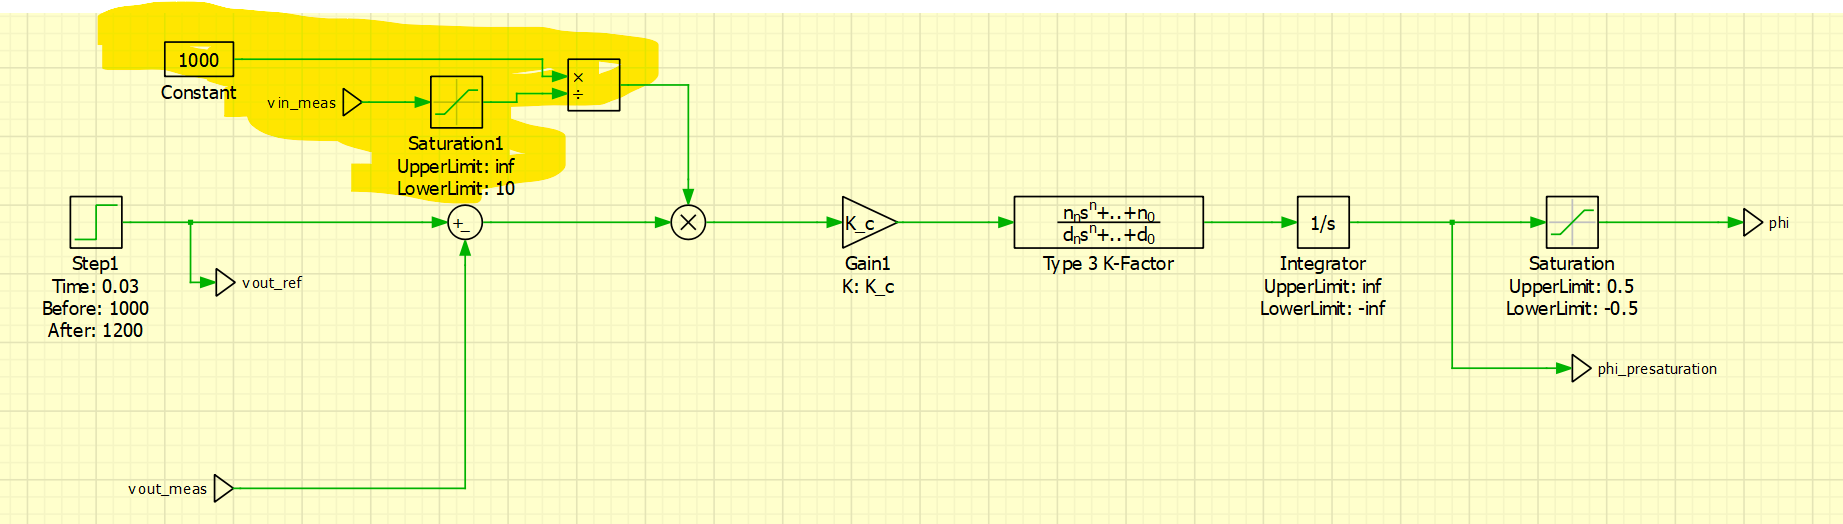

That results in no visible change to the step response.

 How to feedback-linearize $\left(1-|2\phi |\;\right)$? Describing the nonlinearity: As $\phi \;$approaches -0.5 or 0.5, the plant gain approaches zero.

I think I can multiply the output of the controller by this shape:

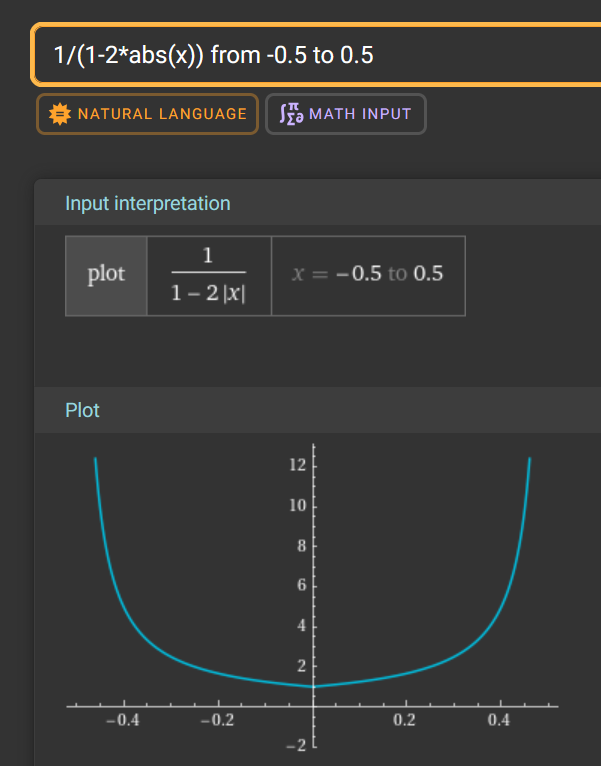

I put it here:

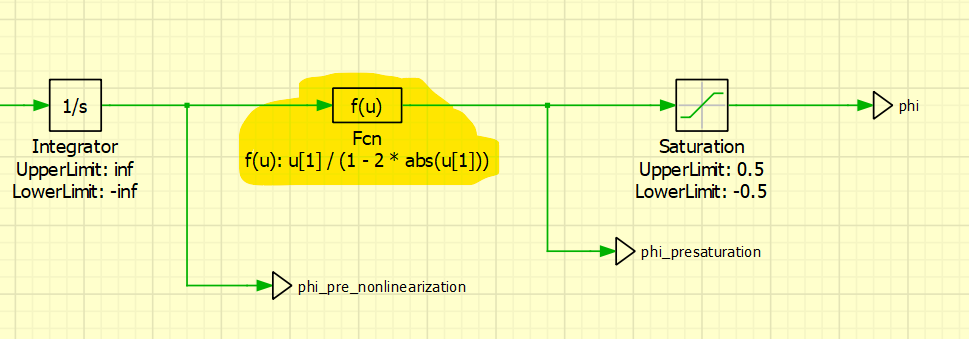

and saved the simulation as `dc_bus_voltage_ctrl_7.plecs`

What happens if I crank up the bandwidth a bit more now?

s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=1e-6;
GpGl = 1/s^2 * 1000/(2*L*N*f*C);

PM_desired = 60;
wc_desired = 2*pi*3000;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z

w_z = 2.4816e+03

w_p

w_p = 1.4318e+05

K_c

K_c = 9.2865e+03

badness. 

I slapped a saturator on the linearizing term to stop it from blowing up due to divide by zero.

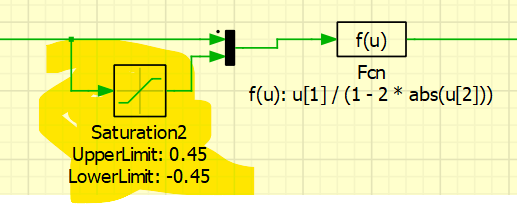

I cranked the bandwidth up but that doesn't solve the issue of the controller not resolving the steady state error quickly. Why does the controller give up here?

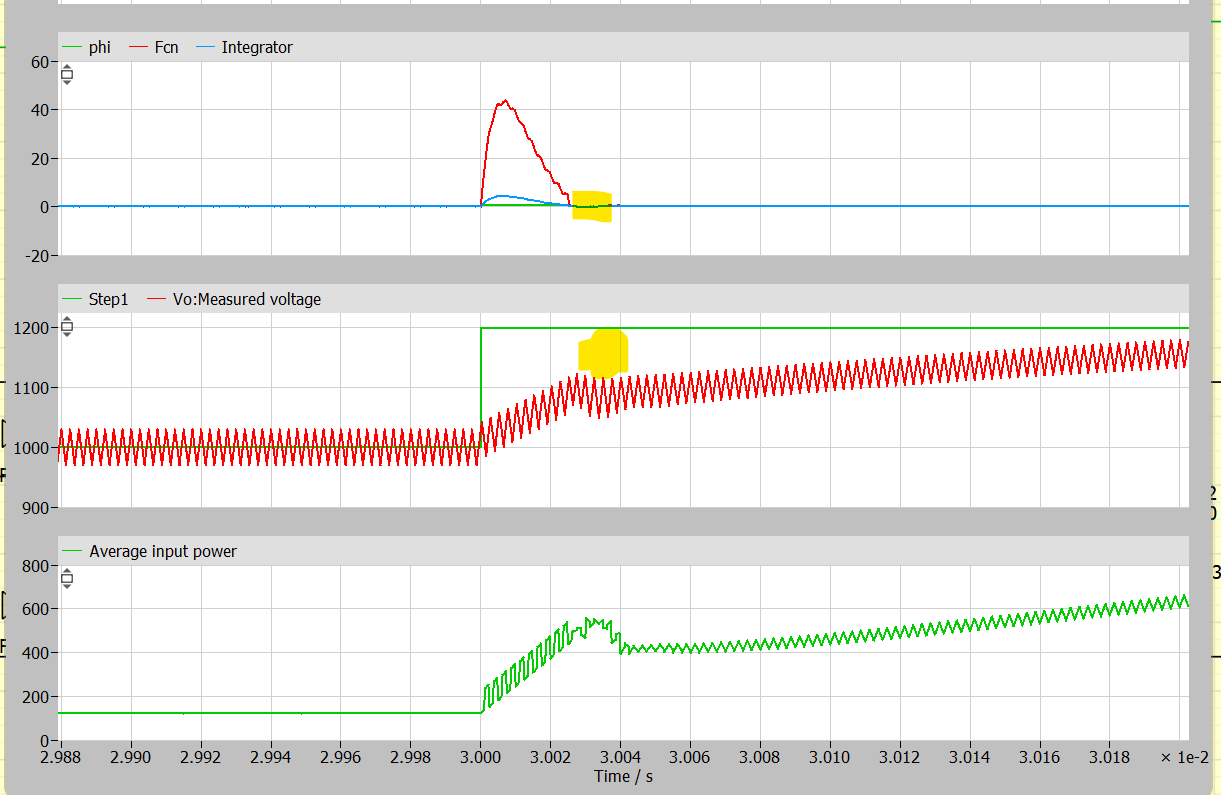

The feedback linearization stuff basically made no improvement over `dc_bus_voltage_ctrl_6.plecs`, the last model without any nonlinear compensation.

I copied it to `dc_bus_voltage_ctrl_9.plecs` The original controller gains were:

w_z = 827.197

w_p = 4.77e4

K_c = 343.9

Increasing K_c doesn't seem to help.

Intuitively, the bandwidth of the controller should be similar order of magnitude to the plant dynamics. The thing limiting the speed of the plant response is still the output capacitor. Let's make it even smaller?  Ripple is only 1V right now.

s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=0.1e-6;
GpGl = 1/s^2 * 1000/(2*L*N*f*C);

PM_desired = 60;
wc_desired = 2*pi*1000;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z

w_z = 827.1970

w_p

w_p = 4.7726e+04

K_c

K_c = 34.3944

at wc_desired = 3kHz, that power curve looks like The Grinch! Let's turn down the bandwidth to 1kHz.

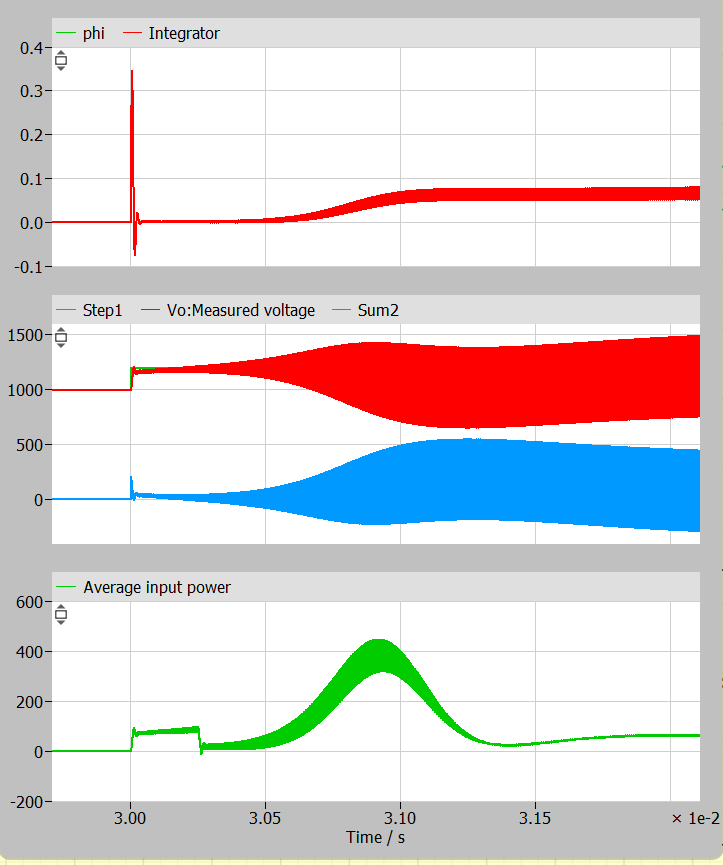

It seems clear now that the issue is in the controller. It has some fast dynamics (yellow) and some slow dynamics (blue). The fast dynamics could be slower and the slow dynamics could be faster. Why I don't see the same dynamics in MATLAB still evades me.

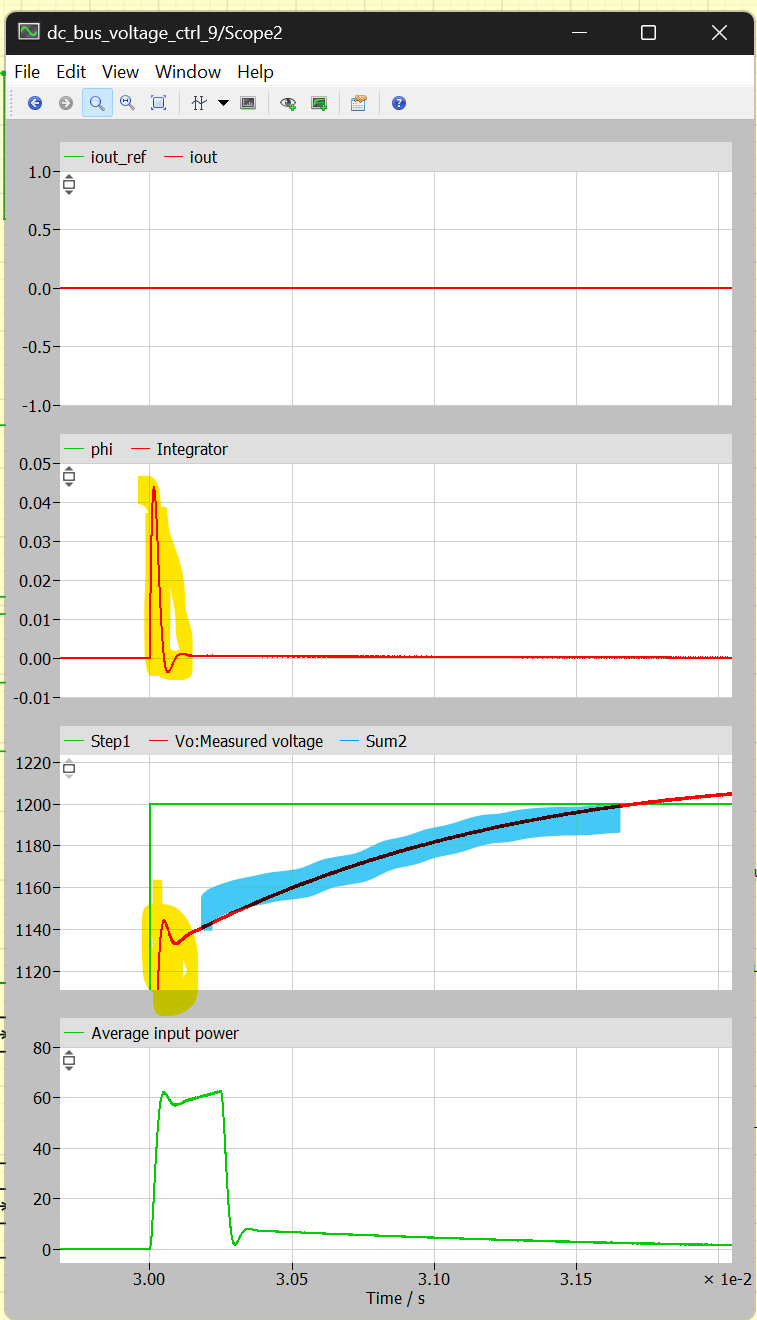

s = tf('s');
N=1;
L=100e-6;
f=400e3;
C=0.1e-6;
GpGl = 1/s^2 * 1000/(2*L*N*f*C);

PM_desired = 60;
wc_desired = 2*pi*1000;
[GpGl_mag, GpGl_phase] = bode(GpGl, wc_desired);
phi_boost = PM_desired - GpGl_phase - 90;
k = tand(phi_boost / 4 + 45);
w_z = wc_desired / k;
w_p = k * wc_desired;
Gc_unitygain = 1/s * (1 + s/w_z)^2 / (1 + s/w_p)^2;
GcGpGl_unitygain = Gc_unitygain * GpGl;
[GcGpGl_unitygain_mag, ~] = bode(GcGpGl_unitygain, wc_desired);
K_c = 1/abs(GcGpGl_unitygain_mag);
w_z

w_z = 827.1970

w_p

w_p = 4.7726e+04

K_c

K_c = 34.3944

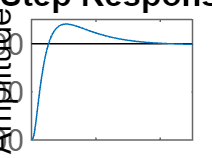


Gc = K_c * Gc_unitygain;
GcGpGl = Gc * GpGl;
figure;
% step the closed loop system from 1000 to 1200
Config = RespConfig('InputOffset', 1000, 'Amplitude', 200);
G_cl = feedback(GcGpGl, 1);
step(G_cl, Config);

The model stepped seems to have captured the low frequency dynamics but not the high frequency dynamics